# Example 6.2: PCA Estimation for Gibbs Reactor

Note: this script reproduces Example 6.2 (Section 6.1.1) of **Statistics for Chemical Engineers**: estimating a linear model of conversion in the space of principal components. Victor Z UW-Madison, 2020 PCA estimation for Gibbs reactor

clc; clear all; close all hidden; format short e;

## Data

generate dataset get data (pressure, conversion, flow co, flow h2, flow ch3oh)

load ('./Data/gibbs_covariance.dat')
datat=gibbs_covariance;
% get temperature data
load ('./Data/gibbs_lowtemp_class.dat')
datan=gibbs_lowtemp_class;
% join data (pressure, conversion, flow co, flow h2, flow ch3oh, temperature)
data=[datat datan(:,1)];

% perturb data with noise
rng(1); % For reproducibility 
[S,n]=size(data);
data(:,2)=data(:,2)+normrnd(0,0.05,S,1);

## Estimation with all inputs and with principal components

construct input-output data matrices

Y=data(:,2);
X=data(:,[1 3 4 5 6]);
[S,n]=size(X);
% join data (ones, pressure, flow co, flow h2, flow ch3oh, temperature)
X=[ones(S,1) X]; % add ones to introduce bias parameter
[S,n]=size(X);

## apply standard estimation

theta=(X'*X)\(X'*Y)

theta =   -4.2793e+00
   6.7452e-04
  -5.5330e-02
   3.1162e-02
   1.5137e-02
  -1.5188e-02


Yhat=X*theta;
e=Yhat-Y;
MSE=mean(e.^2)

MSE =    2.4414e-03

sig2=var(e);
Covtheta=sig2*inv(X'*X)

Covtheta =   -2.0292e+10  -3.2529e-05  -8.2792e+08   2.0757e+08  -4.1279e+08  -3.6794e+07
  -3.2529e-05   3.1941e-07   7.1517e-08   1.3643e-07  -7.1766e-07  -5.2815e-08
  -8.2792e+08   7.1517e-08   6.5942e+06  -5.2935e+05   5.5355e+06   8.3360e+05
   2.0757e+08   1.3643e-07  -5.2935e+05  -3.3825e+05  -1.2058e+06   8.2853e+04
  -4.1279e+08  -7.1766e-07   5.5355e+06  -1.2058e+06   3.1238e+06   9.9930e+05
  -3.6794e+07  -5.2815e-08   8.3360e+05   8.2853e+04   9.9930e+05  -1.6510e+05


diag(Covtheta)

ans =   -2.0292e+10
   3.1941e-07
   6.5942e+06
  -3.3825e+05
   3.1238e+06
  -1.6510e+05


lamk=eigs(X'*X)

lamk =    1.4543e+08
   2.3622e+05
   1.9739e+03
   3.1088e-08
   4.1085e-10
  -7.3973e-14


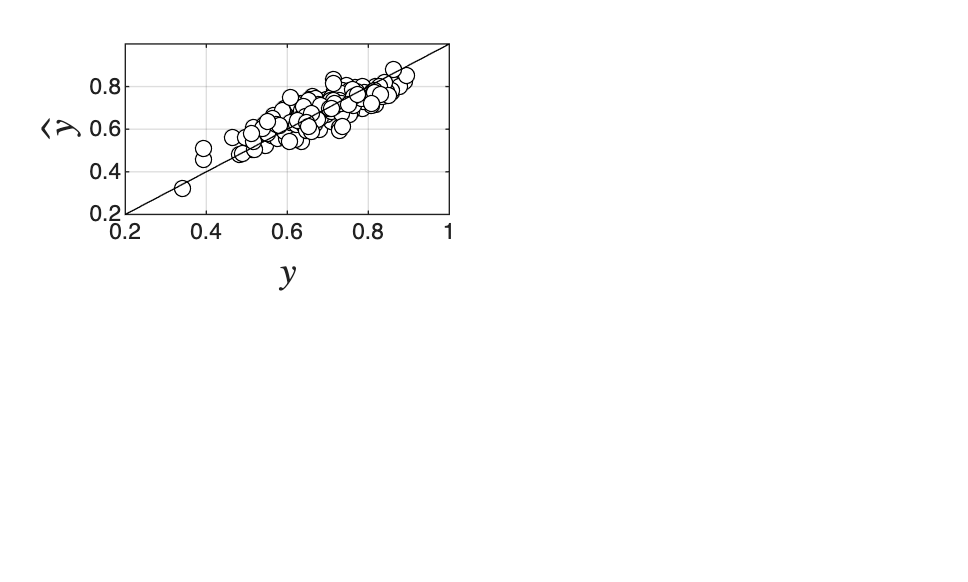


% compare predictions and observations
figure(1)
subplot(2,2,1)
xx=linspace(0,1);
plot(Y,Yhat,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])

## now apply PCA estimation

% form kernel matrix and compute eigenvectors and eigenvalues
Sigma=X'*X;
[W,lam]=eigs(Sigma);
lam=diag(lam)

lam =    1.4543e+08
   2.3622e+05
   1.9739e+03
   3.1076e-08
   4.0959e-10
  -7.4046e-14



% eliminate small eigenvalues
n1=3;
W1=W(:,1:n1);
L1=diag(lam(1:n1));

% project input data
T1=X*W1;

% estimate parameters
gamma=inv(T1'*T1)*T1'*Y

gamma =    8.9967e-04
   2.6021e-03
   3.3798e-03


thetan=W1*gamma

thetan =    4.1833e-06
   6.7452e-04
  -1.8452e-03
  -2.0171e-03
   2.2635e-03
   2.4395e-03


Yhatn=X*thetan;
en=Yhatn-Y;
MSE=mean(en.^2)

MSE =    2.4414e-03

sig2=var(en);
Covthetan=sig2*(W1*inv(L1)*W1')

Covthetan =    7.3422e-13  -4.7719e-10  -3.6036e-10  -4.2704e-10   4.3379e-10   4.2816e-10
  -4.7719e-10   3.1941e-07   2.3268e-07   2.7449e-07  -2.8040e-07  -2.7827e-07
  -3.6036e-10   2.3268e-07   1.7713e-07   2.1012e-07  -2.1317e-07  -2.1015e-07
  -4.2704e-10   2.7449e-07   2.1012e-07   2.4943e-07  -2.5283e-07  -2.4903e-07
   4.3379e-10  -2.8040e-07  -2.1317e-07  -2.5283e-07   2.5655e-07   2.5296e-07
   4.2816e-10  -2.7827e-07  -2.1015e-07  -2.4903e-07   2.5296e-07   2.4968e-07


diag(Covthetan)'

ans =    7.3422e-13   3.1941e-07   1.7713e-07   2.4943e-07   2.5655e-07   2.4968e-07


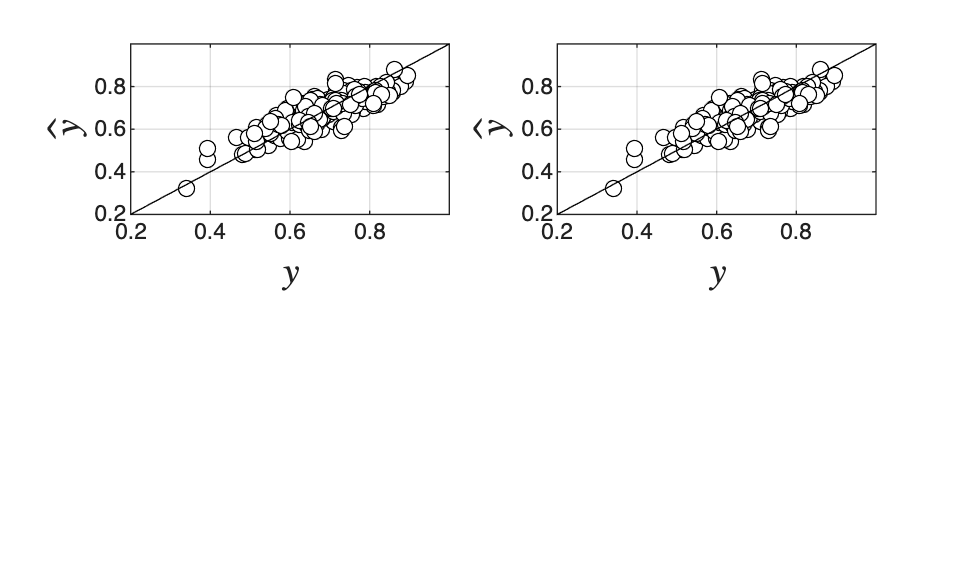


% compare predictions and observations
figure(1)
subplot(2,2,2)
xx=linspace(0,1);
plot(Y,Yhatn,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])

print -depsc ch6_gibbs_pca_fit.eps

## Note

As in the book, estimating in the reduced space removes the redundancy and gives highly precise parameters: cleaning the input data improves the model.